% Dane wejściowe
Ia = 0.598;
Ib = 0.356 * exp(1)^(deg2rad(-120) * 1i);
Ic = 0.306 * exp(1)^(deg2rad(120) * 1i);
In = -(Ia + Ib + Ic);

% Obliczenie kąta prądu neutralnego względem sumy prądów fazowych
angle_deg = rad2deg(angle(In));

% Wyświetlenie kąta
disp(['Kąt prądu neutralnego Iz: ', num2str(angle_deg), ' stopni']);

Kąt prądu neutralnego Iz: 170.7881 stopni


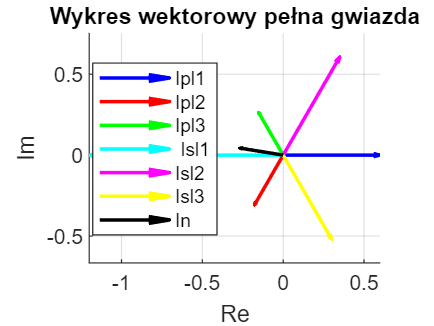


Iar=-1.2;
Ibr=-0.7* exp(1)^(deg2rad(-120)*1i);
Icr=-0.6* exp(1)^(deg2rad(120)*1i);
% Przygotowanie danych do wykresu
Imag = [Ia, Ib, Ic,Iar,Ibr,Icr];
Re = real(Imag);
Im = imag(Imag);

% Tworzenie wektorów dla wykresu
figure;
hold on;
quiver(0, 0, Re(1), Im(1), 0, 'b', 'LineWidth', 1.5);
quiver(0, 0, Re(2), Im(2), 0, 'r', 'LineWidth', 1.5);
quiver(0, 0, Re(3), Im(3), 0, 'g', 'LineWidth', 1.5);
quiver(0, 0, Re(4), Im(4), 0, 'c', 'LineWidth', 1.5);
quiver(0, 0, Re(5), Im(5), 0, 'm', 'LineWidth', 1.5);
quiver(0, 0, Re(6), Im(6), 0, 'y', 'LineWidth', 1.5);
quiver(0, 0, real(In), imag(In), 0, 'k', 'LineWidth', 1.5);
% Legenda
legend('Ipl1', 'Ipl2', 'Ipl3',' Isl1','Isl2','Isl3','In','Location', 'Best');

% Konfiguracja osi
axis equal;
xlabel('Re');
ylabel('Im');
grid on;
title('Wykres wektorowy pełna gwiazda');